% set up for the script
clear; close all; clc;
% add the path to Cheng's prepared functions
addpath('SGML_LMNN')

## Create the dataset

% Gaussian Distribution
% n_feature = 2; % number of features for each data point
% train_num = 210; % number of training points
% val_num = 10; % number of validation points
% 
% cpos_center = [3,10]; % coordinates of the center of the +1 cluster
% cpos_scale = [1, 2]; % standard deviation of the +1 cluster
% cneg_center = [30, 0]; % coordinates of the center of the -1 cluster
% cneg_scale = [2, 1]; % standard deviation of the -1 cluster
% 
% rng(0); % determine the seed
% 
% %% create the training set
% train_des = randn(train_num, n_feature);
% train_lbls = ones(train_num, 1);
% % create the +1 cluster
% train_des(1:floor(train_num/2),1) = cpos_scale(1) * train_des(1:floor(train_num/2),1) + cpos_center(1);
% train_des(1:floor(train_num/2),2) = cpos_scale(2) * train_des(1:floor(train_num/2),2) + cpos_center(2);
% % create the -1 cluster
% train_des(floor(train_num/2)+1:end,1) = cneg_scale(1) * train_des(floor(train_num/2)+1:end,1) + cneg_center(1);
% train_des(floor(train_num/2)+1:end,2) = cneg_scale(2) * train_des(floor(train_num/2)+1:end,2) + cneg_center(2);
% train_lbls(floor(train_num/2)+1:end) = -1;
% 
% %% create the validation set
% val_des = randn(val_num, n_feature);
% val_lbls = ones(val_num, 1);
% % create the +1 cluster
% val_des(1:floor(val_num/2),1) = cpos_scale(1) * val_des(1:floor(val_num/2),1) + cpos_center(1);
% val_des(1:floor(val_num/2),2) = cpos_scale(2) * val_des(1:floor(val_num/2),2) + cpos_center(2);
% % create the -1 cluster
% val_des(floor(val_num/2)+1:end,1) = cneg_scale(1) * val_des(floor(val_num/2)+1:end,1) + cneg_center(1);
% val_des(floor(val_num/2)+1:end,2) = cneg_scale(2) * val_des(floor(val_num/2)+1:end,2) + cneg_center(2);
% val_lbls(floor(val_num/2)+1:end) = -1;

% Whole numbers
n_feature = 3; % number of features for each data point
n_sample = 4; % number of training points

train_des = reshape(1:(n_sample*n_feature), [n_sample, n_feature]);
train_lbls = ones(n_sample,1);
train_lbls(floor(n_sample/2)+1:end) = -1;

## Load the dataset from the disc

% load('../../data/fe_exp/cheng_snap/data.mat')
% train_des = cast(train_des, 'double');
% train_lbls = train_lbls.';
% train_num = size(train_des, 1);

% visualize the dataset
% figure;
% scatter(train_des(1:floor(train_num/2),1),train_des(1:floor(train_num/2),2),25,'red','filled');
% hold on;
% scatter(train_des(floor(train_num/2)+1:end,1),train_des(floor(train_num/2)+1:end,2),25,'blue','filled');
% legend('spike', 'no spike');
% hold off;

## Train the model

borrowed from RUN_ME.m from Cheng's code.

data_feature = train_des;
data_label = train_lbls;
clear train_des train_lbls % to save space
%[n_sample,n_feature] = size(data_feature); % number of samples, number of features

%=main parameters for SGML=================================================
C=n_feature; % constraint of the trace of M
rho=1e-5; % tolerance to make sure M is positive definite during optimization
lobpcg_random_control=0; % random seed for computing the first eigenvector for the first time using LOBPCG
options = optimoptions('linprog','Display','none','Algorithm','interior-point'); % linear program (LP) setting for Frank-Wolfe algorithm
options.OptimalityTolerance = 1e-2; % LP optimality tolerance
options.ConstraintTolerance = 1e-4; % LP interior-point constraint tolerance
FW_dia_offdia_tol=1e-3; % Frank-Wolfe tolerance when optimizing the diagonals + one row/column of off-diagonals
FW_full_tol=1e-5; % Frank-Wolfe tolerance when optimizing the full metric matrix M
max_iter=1e3; % maximum number of iterations for each round of Frank-Wolfe optimization
%==========================================================================

%=parameters for Frank-Wolfe step size optimization========================
GS_or_NR=2; % Frank-Wolfe step size optimization using 1) golden section search or 2) Newton-Raphson method
tol_golden_search=5e-1; % tolerance of golden section search
tol_NR=5e-1; % Newton-Raphson tolerance
tol_GD=5e-1; % gradient descent bisection tolerance
%==========================================================================

%=other parameters=========================================================
gamma = 1; % free factor in the objective function
beta = 1; % free factor in the objective function
nv_od=2*n_feature-1; % number of LP variables when optimizing the diagonals + one row/column of off-diagonals
nv_full=n_feature+(n_feature*(n_feature-1))/2; % number of LP variables when optimizing the full metric matrix M
zz=logical(tril(ones(n_feature),-1)); % indices of the lower triangular part of M
dia_idx=(1:n_feature+1:n_feature^2)'; % indices of the diagonals of M
num_list=1:n_feature; % indices of graph nodes of M where the nodes are currently connected
league_vec = ones(n_feature,1); % color set of graph nodes of M
league_vec(2:2:end)=-1; % set it like this so that the odd nodes are blue and even nodes are red
bins=ones(1,n_feature); % the number of the unique numbers of bins represents the number of subgraphs of M
%==========================================================================
% find number of delta optimization variables
[n_delta,delta_idx] = get_delta_variables(data_label, n_sample);

%=Initialize M and deltas=============================================================
M0=initial_M(n_feature,2); % initial M as a [1-dense matrix] or [2-sparse matrix]
delta0=Inf*ones([8,1]);

% [M0,league_vec] = determine_initial_M_appropriate_colors(data_cov,...
%     n_feature,...
%     [],...
%     [],...
%     [],...
%     2);

rng(lobpcg_random_control);
[fv1,~] = ...
    lobpcg_fv(randn(n_feature,1),M0,1e-12,200); % compute the first eigenvector for the first time using LOBPCG
scaled_M = (1./fv1) .* M0 .* fv1'; % compute the similarity-transformed M
scaled_factors = (1./fv1) .* ones(n_feature) .* fv1'; % get the scalars of M
%==========================================================================

[LP_A_sparse_i,...
    LP_A_sparse_j,...
    LP_A_sparse_s,...
    LP_b,...
    LP_lb,...
    LP_ub] = LP_setting(n_feature,n_delta,rho,data_feature,delta_idx); % get parts of the linear constraints ready for running Matlab linprog

% for debugging purposes
save('../../data/fe_exp/cheng_swap/M0andfv1.mat', 'M0', 'fv1')

%=run SGML=================================================================
disp('**starting SGML.');

**starting SGML.


[M]=SGML_main_yasaman(M0,...
    delta0,...
    data_feature,...
    data_label,...
    n_sample,...
    n_feature,...
    n_delta,...
    delta_idx,...
    tol_NR,...
    tol_GD,...
    rho,...
    max_iter,...
    GS_or_NR,...
    tol_golden_search,...
    options,...
    FW_dia_offdia_tol,...
    FW_full_tol,...
    C,...
    gamma,...
    beta,...
    nv_od,...
    nv_full,...
    zz,...
    dia_idx,...
    num_list,...
    league_vec,...
    bins,...
    fv1,...
    scaled_M,...
    scaled_factors,...
    LP_A_sparse_i,...
    LP_A_sparse_j,...
    LP_A_sparse_s,...
    LP_b,...
    LP_lb,...
    LP_ub); % run SGML

initial objective value = Inf
 
converged objective value = 3.3427
minimal eigenvalue of M = 0.09679


disp('**done with SGML.');

**done with SGML.


%==========================================================================

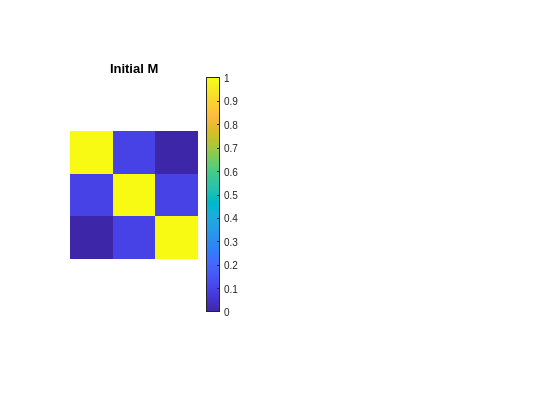

%% visualize the initial metric matrix M0
figure(1);subplot(1,2,1);imagesc(M0);title('Initial M');axis off equal;colorbar; % visual check M0

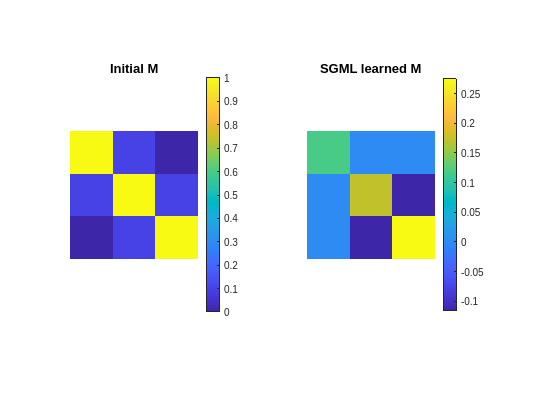

%% visualize the SGML learned metric matrix M
subplot(1,2,2);imagesc(M);title('SGML learned M');axis off equal;colorbar; % visual check M

## save the optimized metric matrix M

% fullM = full(M);
% save('../../data/fe_exp/cheng_snap/metric.mat', 'fullM')